# Mechanical Systems Modeling & Simulation Using Simulink (Using Mathematical Equations which is Much Harder Compared to Physics-based Modeling in SimScape!)

## Task #1. Understand the Project Scope 

System modeling is used to map the reality (real dynamic system such as a car) into a set of simplified mathematical equations (model).

A system model is a set of governing mathematical equations which describe the model's dynamical behavior.

Once you have a governing mathematical equations, you can then simulate the system and assess its performance using simulation tools such as Matlab/Simulink.

As a rule of thumb, we keep the model simple at first and add complexity as needed later on!

The dynamics of many systems, whether they are mechanical, electrical, thermal, economic, etc., may be described in terms of differential equations. Such differential equations may be obtained by using physical laws such as Newton's laws for mechanical systems or Kirchhoff's laws for electrical systems. 

Consider a simple mass spring damper system as shown below:

               Assume M = 1 Kg, b = 1 Ns/m, k =1 N/m

                                                                             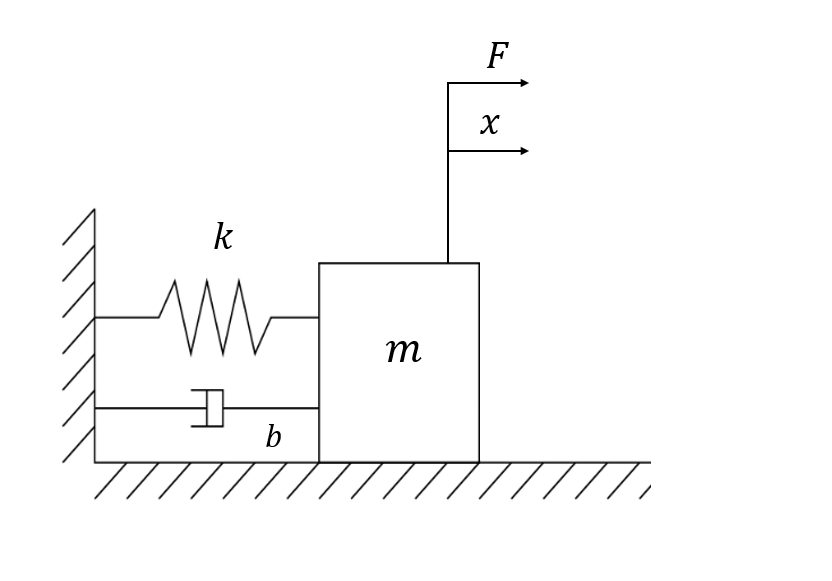

## Task #2: Draw the Free Body Diagram & Derive Mathematical Equations

Let's draw the free body diagram of the system, The Force F is the input to the system and displacement x is the output.

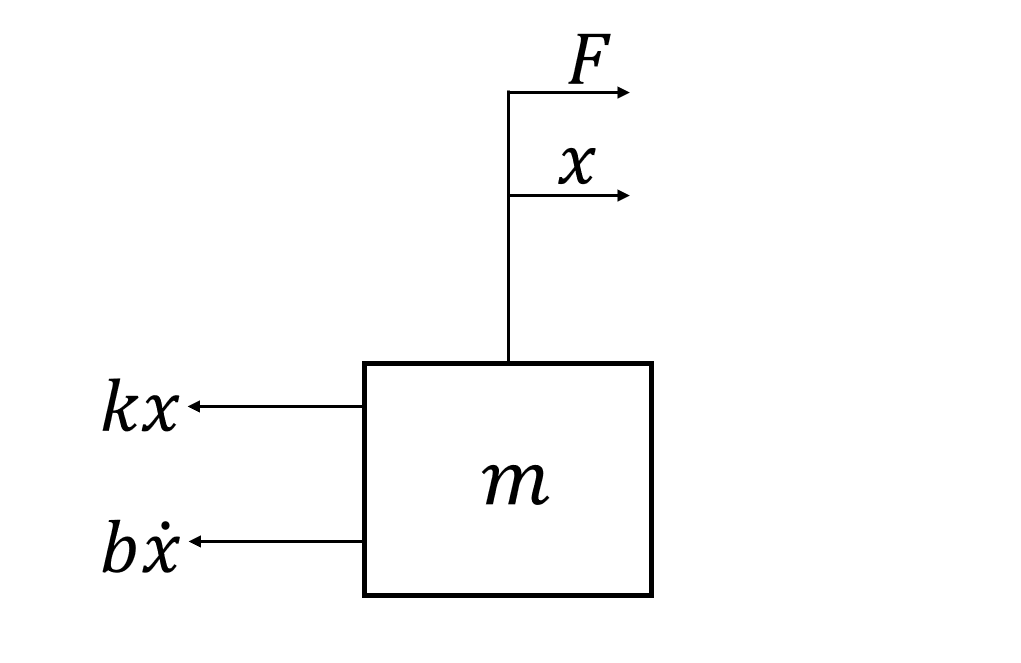

The spring force is directly proportianal to the displacement $x$ while the viscous damping force is directly proportional to the velocity $\dot{x}$.

Using Newton's Second law of motion, the system can be described by the following equations:

                                                                    
$$M\ddot{x} =F-b\dot{x} -\textrm{kx}$$


                                                                  
$$ẍ=1/M\left(F-\textrm{bx}̇-\textrm{kx}\right)$$


## Task #3. Build Simulink Model 

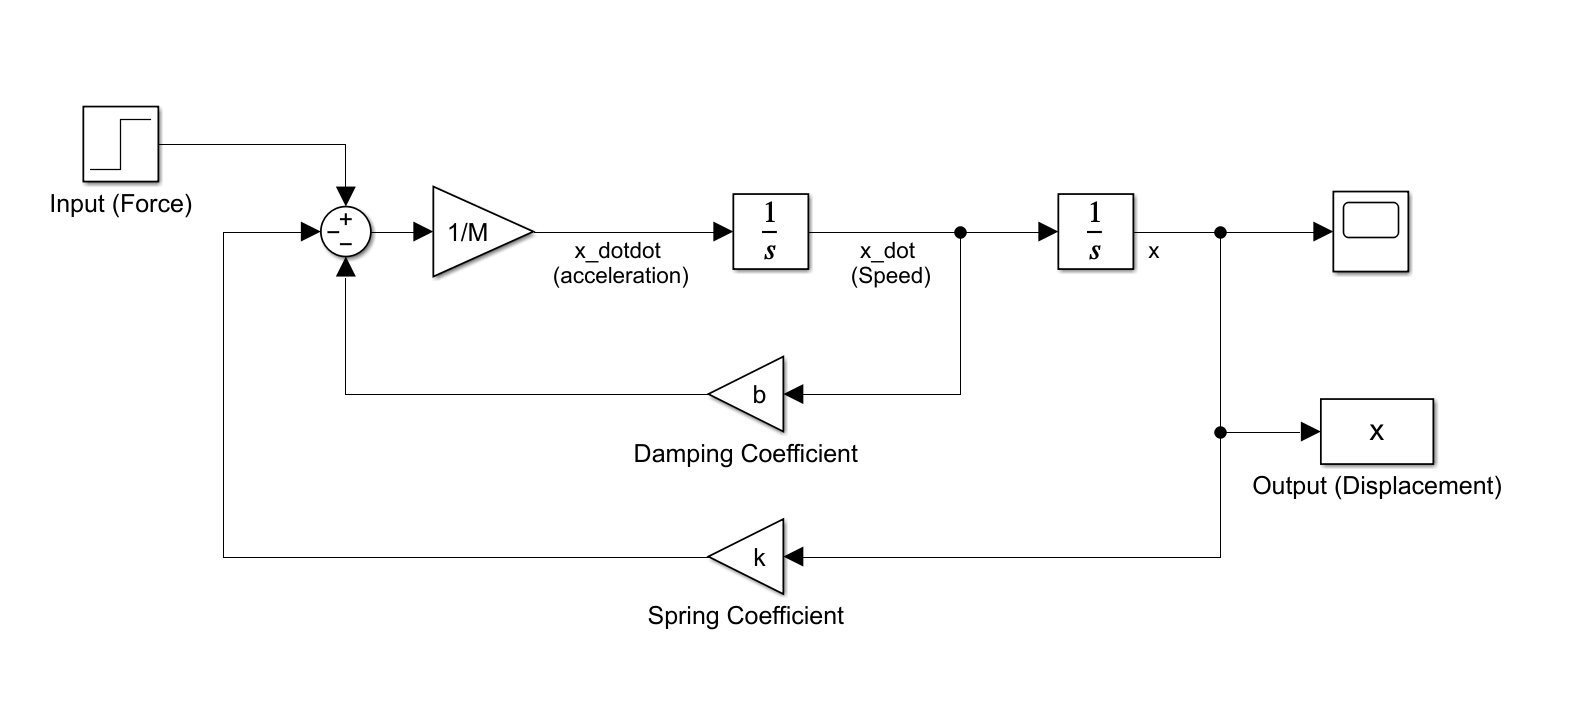

## Task #4: Simulate the Model

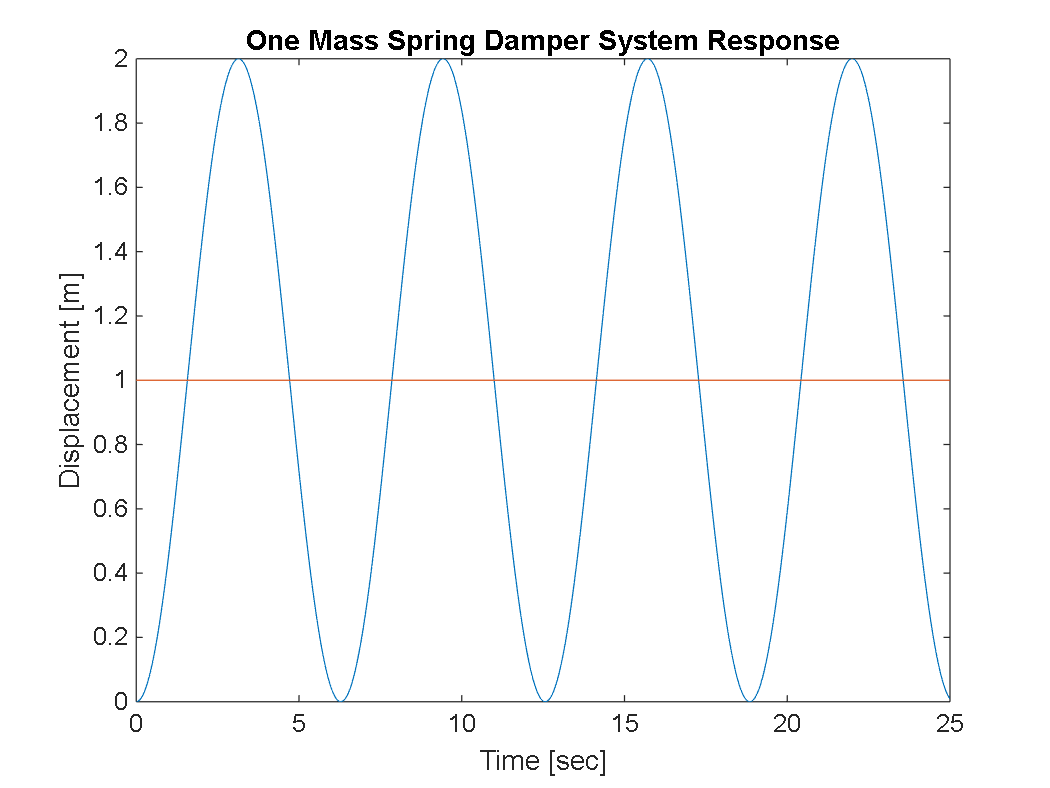

% Define Model Parameters
Sim_Time = 25;
F = 1;
M = 1;
b =0;
k = 1;
sim('mass_spring_damper_simulink.slx');
figure
plot(x)
hold on 
plot(F)
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('One Mass Spring Damper System Response')

## Final Capstone Project Overview

In this final end of day project, please complete the following tasks: 

- Draw the free body diagram for the following system.

- Build a two degrees of freedom mechanical system using Simulink as shown below. Note that the system contains two masses m1 and m2, two springs with spring constants k1 and k2, and two dampers with damping coefficients b1 and b2. 

                  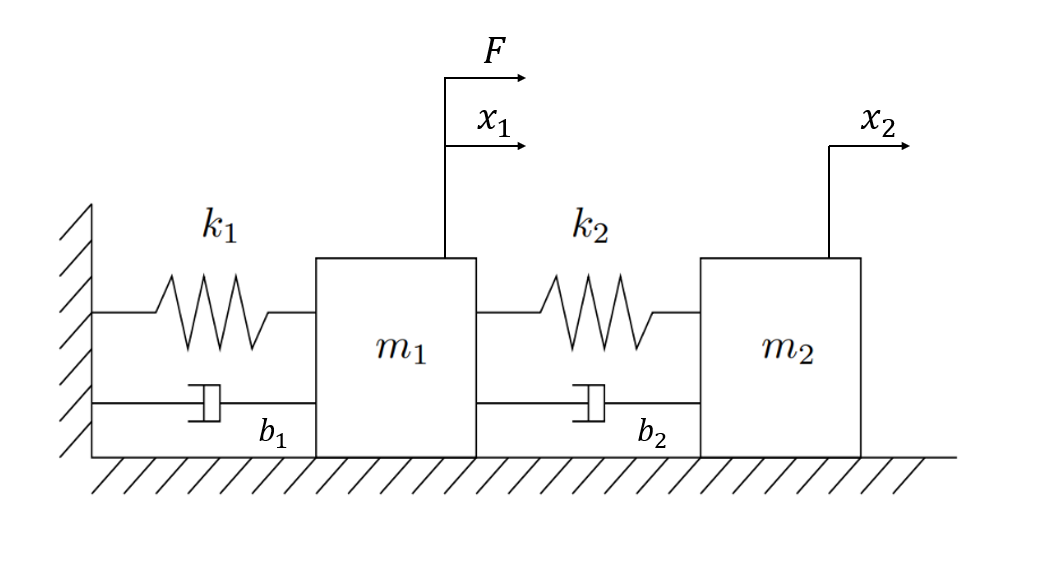

        3. Assuming m1 = 1 Kg, b1 = 1 Ns/m, k1 = 1 N/m, m2 = 1 Kg, b2 = 1 Ns/m, k2 = 1 N/m, apply a unit step input F and simulate the system. 

        4. Plot the displacement x1, x2, and Force (input) on one graph.

        5. Assume that the system has no damping element, simulate the system and comment on the results. 

## Final Capstone Project Solution

Using Newton's Second law of motion, the system can be described by the following equations:

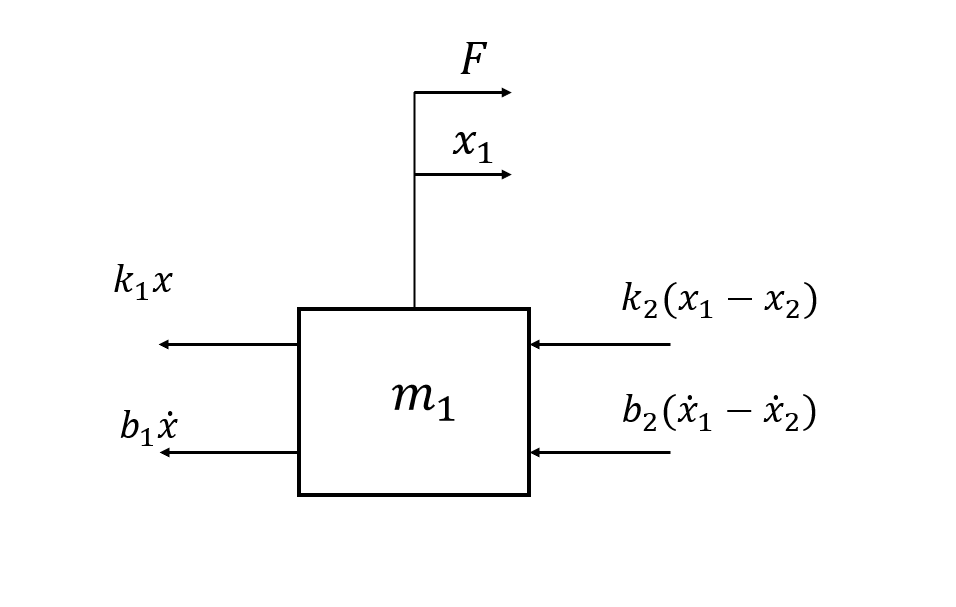

                                                             
$$m_1 \ddot{x_{1\;} } =F-b_{1\;} \dot{x_{1\;} } -k_{1\;} x_{\;1} -k_{\;2} \left(x_1 -x_{2\;} \right)-b_{2\;} \left(\dot{x_{\;1} } -\dot{x_{\;2} } \right)$$


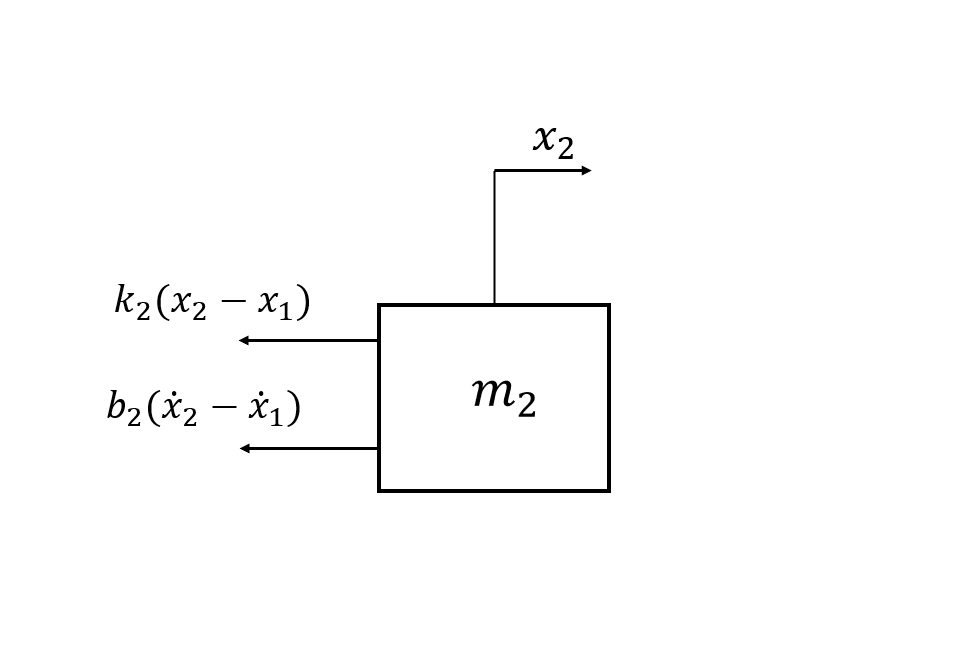


$$m_2 \ddot{x_{2\;} } =-k_{\;2} \left(x_2 -x_{1\;} \right)-b_{2\;} \left(\dot{x_{\;2} } -\dot{x_{\;1} } \right)$$


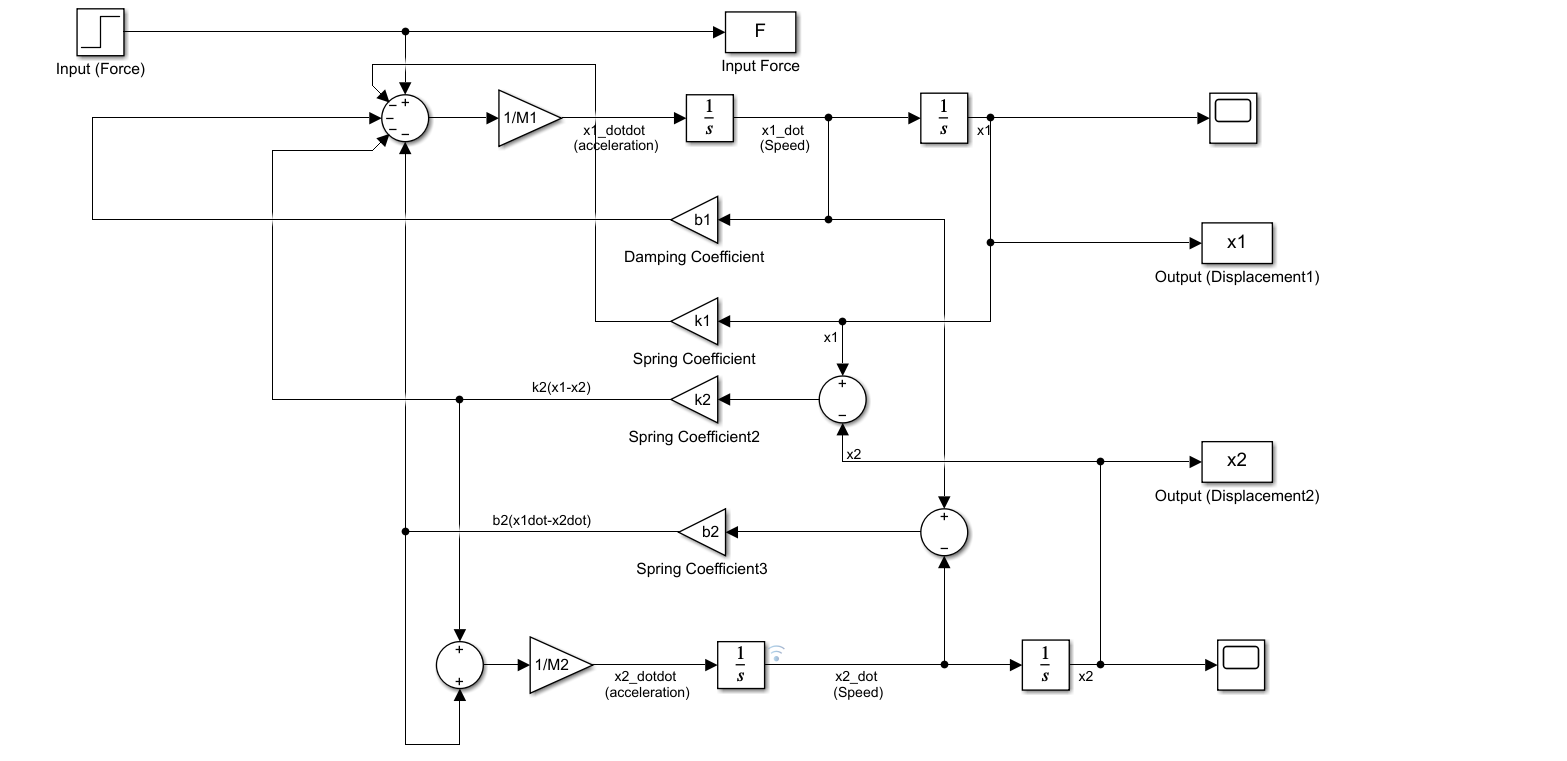

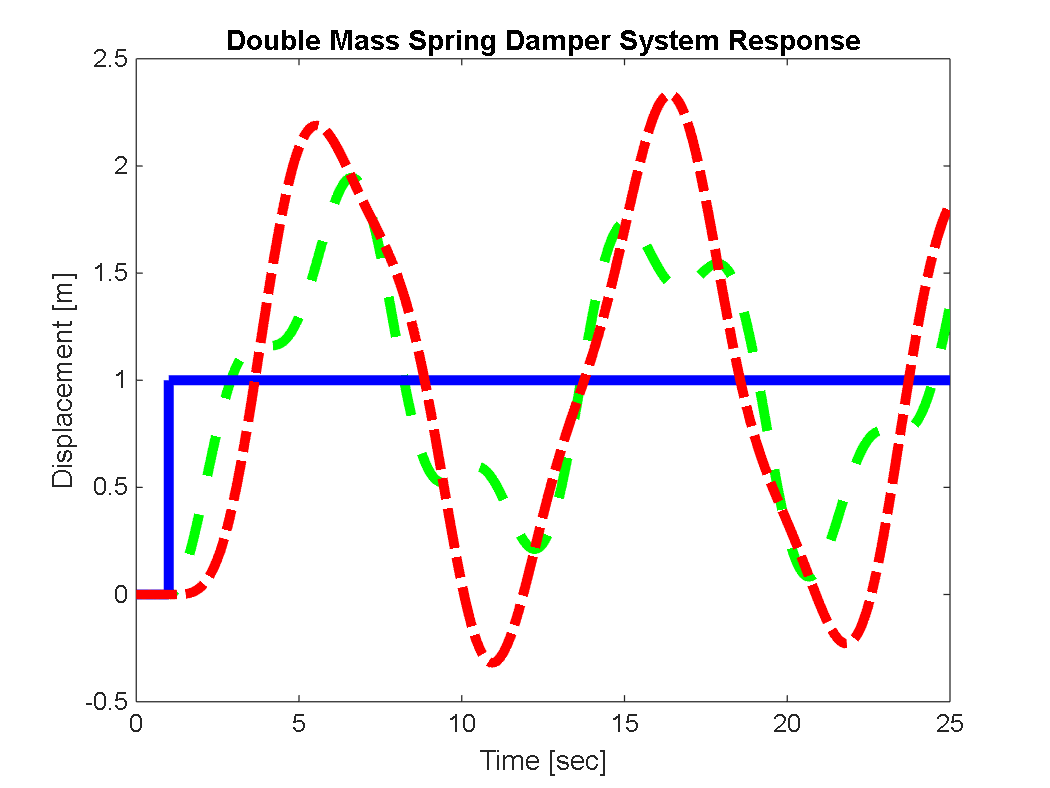

% Define Model Parameters
Sim_Time = 25;
F = 1;
M1 = 1;
b1 =0;
k1 = 1;

M2 = 1;
b2 =0;
k2 = 1;

sim('mass_spring_damper_simulink_project_solution.slx');
figure
plot(x1,'--g','LineWidth',4)

hold on 
plot(F, 'b', 'LineWidth',4)
hold on 
plot(x2,'-.r','LineWidth',4)
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Double Mass Spring Damper System Response')